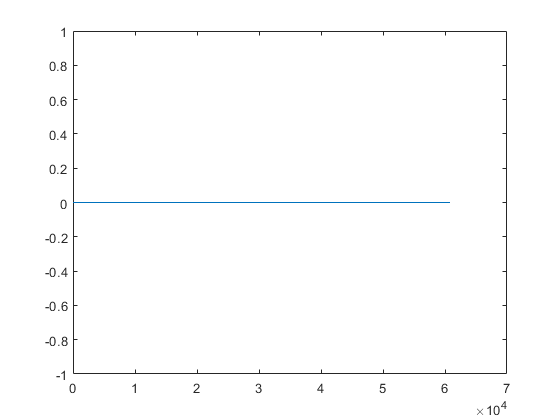

infilenames_cell...
    = {'sample5/F01_22HC010H_BUS.CH1.wav',...
       'sample5/F01_22HC010H_BUS.CH3.wav',...
       'sample5/F01_22HC010H_BUS.CH4.wav',...
       'sample5/F01_22HC010H_BUS.CH5.wav',...
       'sample5/F01_22HC010H_BUS.CH6.wav'};
   
outfilename = 'enhanced.wav';

bf_refactored(infilenames_cell, outfilename);

ref_data = audioread('enhanced_ref.wav');
y_data = audioread(outfilename);

plot(ref_data - y_data);

if sum(ref_data - y_data) == 0
    fprintf('succeed\n');
end

succeed
